- Load Audio

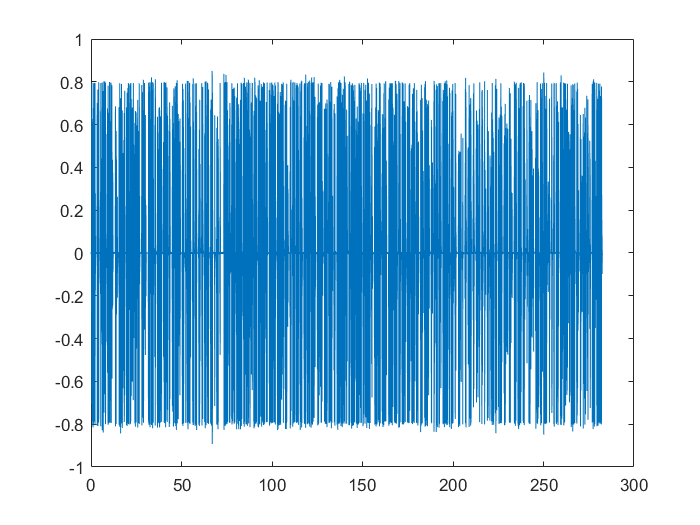

[orig_audio, orig_Fs] = audioread("audio_sample_2.mp3");
t = (1/orig_Fs) * (0:length(orig_audio)-1);
plot(t, orig_audio);

% sound(orig_audio, orig_Fs)

2. Generating Noise

% Adding noise
[noise_sample, noise_Fs] = audioread("noise_sample_2-busy_street.mp3")

noise_sample =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


noise_Fs = 44100

if numel(noise_sample(:,1)) > numel(orig_audio)
    rand_noise_index = randi(abs(numel(noise_sample(:,1)) - numel(orig_audio)) + 1, 1, 1);
    gen_noise = noise_sample(rand_noise_index:rand_noise_index + numel(orig_audio) - 1);
else
    orig_audio = orig_audio(1:length(noise_sample));
    gen_noise = noise_sample(:,1);
    gen_noise = gen_noise';
    t = t(1:length(noise_sample));
end

3. Adding Noise

orig_power = sum(orig_audio.^2);
noise_weakness_factor = 1;
noise_power = sum(gen_noise.^2) * noise_weakness_factor;
firfilt = dsp.FIRFilter;
firfilt.Numerator = fir1(11,0.4);
f_noise = firfilt(gen_noise * sqrt(orig_power/noise_power))

f_noise =    -0.0003   -0.0003   -0.0002   -0.0001   -0.0000    0.0000    0.0000    0.0001    0.0001    0.0000   -0.0001   -0.0003   -0.0004   -0.0004   -0.0004   -0.0003   -0.0002   -0.0002   -0.0002   -0.0002   -0.0001   -0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0001   -0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002


noisy_audio = orig_audio + gen_noise';
% sound(noisy_audio, orig_Fs);
% sound(f_noise', orig_Fs)
% plot(t, f_noise);
% plot(t, noisy_audio)

4. Butterworth Bandpass Filter

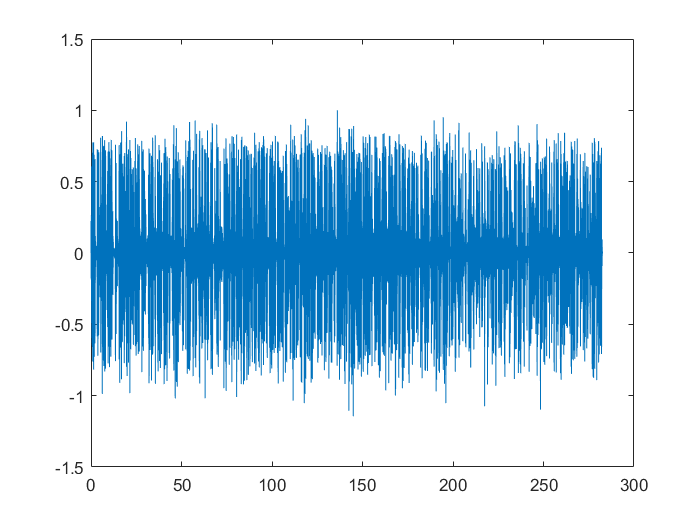

lower_freq = 200 / (orig_Fs/2);
upper_freq = 10000 / (orig_Fs/2);
[b,a] = butter(8, [lower_freq,upper_freq], "bandpass");
bandpass_audio = filter(b,a,noisy_audio);
plot(t, bandpass_audio)

% sound(bandpass_audio, orig_Fs)

5. Savitzky-Golay Filter

order = 9;
frame_len = 39;
sgolay_audio = sgolayfilt(bandpass_audio, order, frame_len);
sound(sgolay_audio, orig_Fs);

6. LMS Noise Cancellation

% aaa

initial_coefficents = (firfilt.Numerator).'-0.01;
step = 0.05; 
lms = dsp.LMSFilter(12,'Method','Sign-Sign LMS',...
   'StepSize',step,'InitialConditions',initial_coefficents);
[clean, error] = lms(sgolay_audio, orig_audio);
sound(error, orig_Fs)
